# Antenna Fabrication with Gerber File Generation

load("patchMicrostripDielectric.mat")
pcb = pcbStack(patchD)

pcb =   pcbStack with properties:

              Name: 'Probe-fed rectangular microstrip patch'
          Revision: 'v1.0'
        BoardShape: [1×1 antenna.Rectangle]
    BoardThickness: 3.8934e-05
            Layers: {[1×1 antenna.Rectangle]  [1×1 dielectric]  [1×1 antenna.Rectangle]}
     FeedLocations: [1.7884e-04 0 1 3]
      FeedDiameter: 2.7652e-05
      ViaLocations: []
       ViaDiameter: []
      FeedViaModel: 'strip'
       FeedVoltage: 1
         FeedPhase: 0
         Conductor: [1×1 metal]
              Tilt: 0
          TiltAxis: [1 0 0]
              Load: [1×1 lumpedElement]


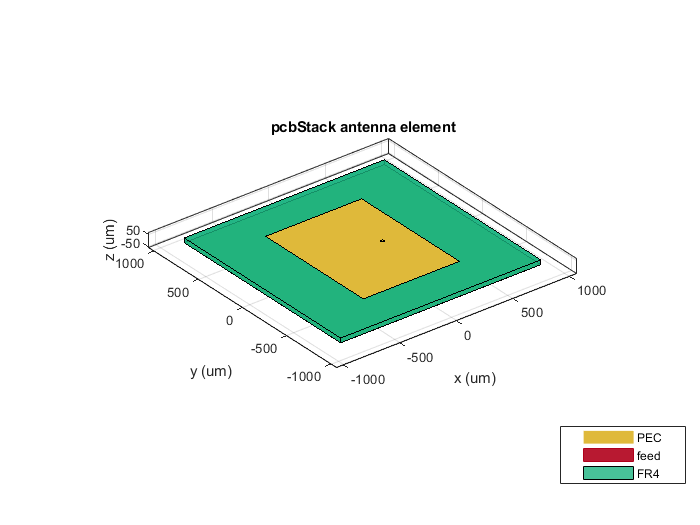

show(pcb)

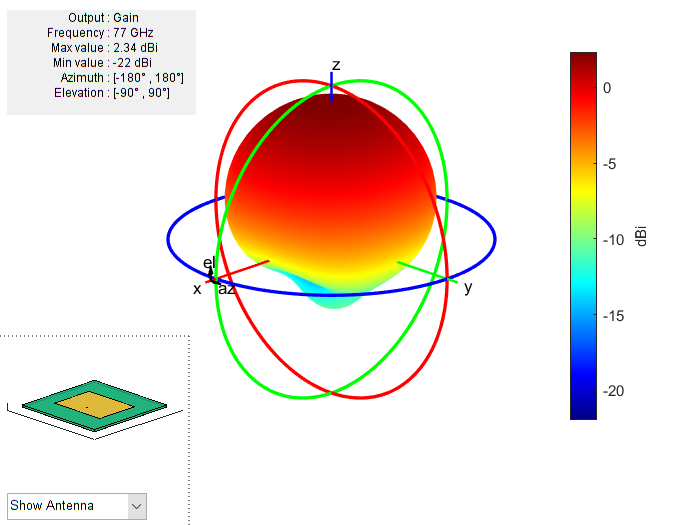

pattern(pcb, 77e9);

W = PCBServices.MayhewWriter

W =   MayhewWriter with properties:

               BoardProfileFile: 'legend'
          BoardProfileLineWidth: 1
                 CoordPrecision: [2 6]
                     CoordUnits: 'in'
              CreateArchiveFile: 0
                 DefaultViaDiam: 3.0000e-04
             DrawArcsUsingLines: 1
                 ExtensionLevel: 1
                       Filename: 'untitled'
                          Files: {}
         IncludeRootFolderInZip: 0
                   PostWriteFcn: @(obj)sendTo(obj)
    SameExtensionForGerberFiles: 0
                    UseExcellon: 1


W.Filename = 'MyPatchAntenna';

C = PCBConnectors.SMA

C =   SMA with properties:

                    Type: 'SMA'
                     Mfg: 'Generic'
                    Part: 'Generic'
              Annotation: 'SMA'
               Impedance: 50
               Datasheet: ''
                Purchase: ''
               TotalSize: [0.0050 0.0050]
           GroundPadSize: [1.0000e-03 1.0000e-03]
       SignalPadDiameter: 1.0000e-03
         PinHoleDiameter: []
           IsolationRing: 0
    VerticalGroundStrips: 0

   Generic Generic


Gb = PCBWriter(pcb, W, C)

Gb =   PCBWriter with properties:

                        Design: [1×1 struct]
                        Writer: [1×1 PCBServices.MayhewWriter]
                     Connector: [1×1 PCBConnectors.SMA]
           UseDefaultConnector: 0
    ComponentBoundaryLineWidth: 8
         ComponentNameFontSize: []
            DesignInfoFontSize: []
                          Font: 'Arial'
                     PCBMargin: 5.0000e-04
                    Soldermask: 'both'
                   Solderpaste: 1

   See info for details

gerberWrite(Gb)